# Test CNN.m

## Parameters

cnn = CNN();

cnn.x                                      = [];
cnn.y                                      = [];
cnn.divide_param.train_ratio               = 70/100;
cnn.divide_param.validation_ratio          = 15/100;
cnn.divide_param.test_ratio                = 15/100;

cnn.kernel_sizes                           = [2, 2, 2];
cnn.output_size                            = [2, 2, 2];

cnn.number_of_epochs                       = 100;
cnn.batch_size                             = 10;
cnn.learning_rate                          = 0.001;
cnn.number_of_validations_faild            = 20;

cnn.C                                      = @CNN.quadratic_cost_function;
cnn.C_                                     = @CNN.diff_quadratic_cost_function;
cnn.s                                      = @CNN.rectifier_activation_function;
cnn.s_                                     = @CNN.diff_rectifier_activation_function;

delay                                      = 0.1;
number_of_slices                           = 5;

## Neural Network

cnn.init();
N                                         = 100;   % number of data
cnn.make_data(N);
cnn.save('ground_truth_cnn');

## Learning

sigma                                     = 0.01; % gaussian noise to kernels
cnn.add_noise_to_w(sigma);
cnn.add_noise_to_b(sigma);

tic();
cnn.run();
toc();

Elapsed time is 2.353210 seconds.


cnn.save('trained_cnn');

## Show Results

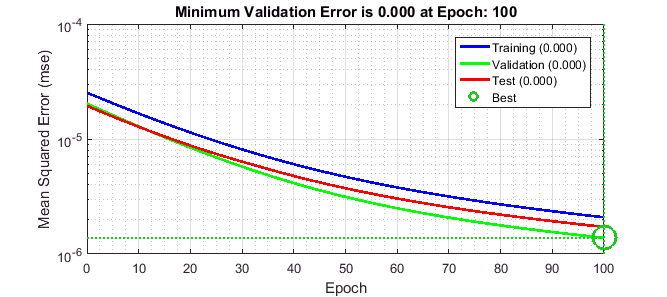

ground_truth_cnn = CNN.load('ground_truth_cnn');
trained_cnn = CNN.load('trained_cnn');

trained_cnn.plot_total_cost_history();